# Podešavanje PID: Z-N metoda odskočnog odziva

clc;
close all;
clear variables;

[L, R, C, E, x2e] = nominalni_parametri();
[G, ~, ~, ~, ue] = linearizacija();

sim_duration = 1; % sec 
time_step = 1e-4; % sec

t0 = 0.5 * sim_duration;
delta_u = 0.1*ue;

## Simulacija

sim_file_name = 'ziegler_nichols_odskocni_sim';
open_system(sim_file_name)
warning ('on','all');
out = sim(sim_file_name);

### Racunanje parametara $N$ i ${\tau}$

[N, i_inflex] = max(out.dy_dt.Data(out.tout > t0))

N = 636.6856

i_inflex = 155

y_t0_plus = out.y.Data(out.tout > t0);
t_t0_plus = out.tout(out.tout > t0);

t_inflex = t_t0_plus(i_inflex);
y_infelx = y_t0_plus(i_inflex);
delta_y = y_infelx - abs(x2e);
delta_t = delta_y / N;
t1 = t_inflex - delta_t;
tau = t1 - t0;
a = N*tau / delta_u;

## Racunanje parametara kontrolera

Kp = 1.2 / a;
Ti = 2 * tau;
Td = tau / 2;
Tf = Td / 20;

## Provera kvaliteta kontrolera

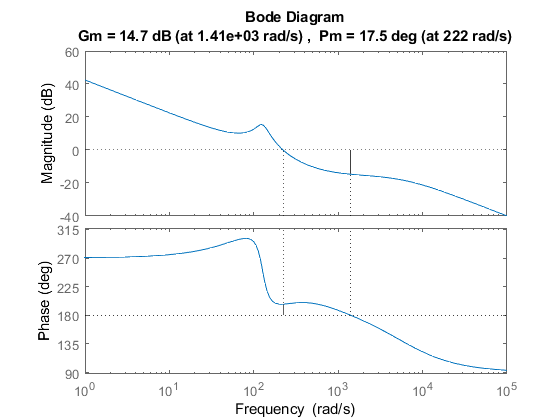

s = tf('s');
K_zno = -Kp * (1 + 1 / Ti / s + Td * s / (Tf * s + 1));
margin(K_zno*G)

## Modifikovanje parametara radi poboljsanja performansi

Ovde mozda moze cak i jedan lead da ide

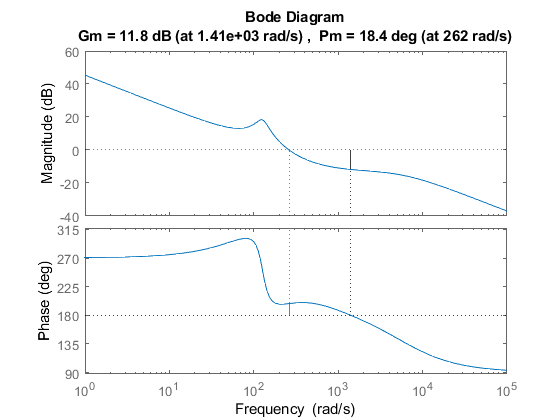

K_zno_mod = K_zno * 1.4;
margin(K_zno_mod * G)

close_system(sim_file_name)